LoadData();

## Calculate the R2 Value for each combination of signals

warning('off','all')
correlatedSignalMatrix = cell(numOfSignals, numOfSignals);
correlatedSignalMatrix2 = cell(numOfSignals, numOfSignals);
for i = 1:numOfSignals
    for j = i:numOfSignals
        if i ~= j
            str = "";
            for k = 1:numOfFeatures
                sig1 = FeaturesAll.(signalName(i) + featureNames(k));
                sig2 = FeaturesAll.(signalName(j) + featureNames(k));
    
                mdl = fitlm(sig1, sig2);
                R2 = mdl.Rsquared.Ordinary;

                %if R2 > 0.9 && R2 < 1
                if R2 > 0.3 && R2 < 0.5
                    str = str + sprintf('%i %s %3g \n', k, featureNames(k), round(R2, 3));  
                    correlatedSignalMatrix{i, j} = [correlatedSignalMatrix{i, j} k];
                end
                correlatedSignalMatrix2{i, j} = [correlatedSignalMatrix2{i, j} R2];
            end
            if (str ~= "")
                disp( sensorNames(i) + " " + sensorNames(j) );
                disp(str)
            end
        end
    end
end

1. 21:07 Angle over Rolls (degrees) 3. 21:12 Actual moment over Rolls (Nm)


6 PeakValue 0.309 



1. 21:07 Angle over Rolls (degrees) 5. 21:20 Actual moment under Rolls (Nm)


6 PeakValue 0.302 



1. 21:07 Angle over Rolls (degrees) 6. 21:28 Vibration measurements (mm per s)


1 ClearanceFactor 0.332 
2 CrestFactor 0.312 
3 ImpulseFactor 0.324 
12 Std 0.368 



1. 21:07 Angle over Rolls (degrees) 7. 21:31 Width position (mm)


5 Mean 0.456 
6 PeakValue 0.455 
7 RMS 0.456 



3. 21:12 Actual moment over Rolls (Nm) 4. 21:17 Angle under roll (degrees)


6 PeakValue 0.377 
7 RMS 0.371 



4. 21:17 Angle under roll (degrees) 5. 21:20 Actual moment under Rolls (Nm)


6 PeakValue 0.367 
7 RMS 0.36 



4. 21:17 Angle under roll (degrees) 7. 21:31 Width position (mm)


7 RMS 0.326 



6. 21:28 Vibration measurements (mm per s) 12. 21:36 Actual force (KN)


5 Mean 0.304 



7. 21:31 Width position (mm) 10. 21:34 Error position for the width (?)


11 Skewness 0.423 



8. 31:32 Height position (?) 9. 21:33 Error position for height (?)


4 Kurtosis 0.419 



8. 31:32 Height position (?) 11. 21:35 Set point force (KN)


1 ClearanceFactor 0.331 



9. 21:33 Error position for height (?) 10. 21:34 Error position for the width (?)


5 Mean 0.304 
7 RMS 0.304 
12 Std 0.326 



correlatedSignalMatrix

correlatedSignalMatrix = 12×12 cell array
    {0×0 double}    {0×0 double}    {[       6]}    {0×0 double}    {[       6]}    {[1 2 3 12]}    {[   5 6 7]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {[     6 7]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {[     6 7]}    {0×0 double}    {[       7]}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 d

## Plot signals that have R2 above threshold

Signal 1:Signal 3 - Features: 1

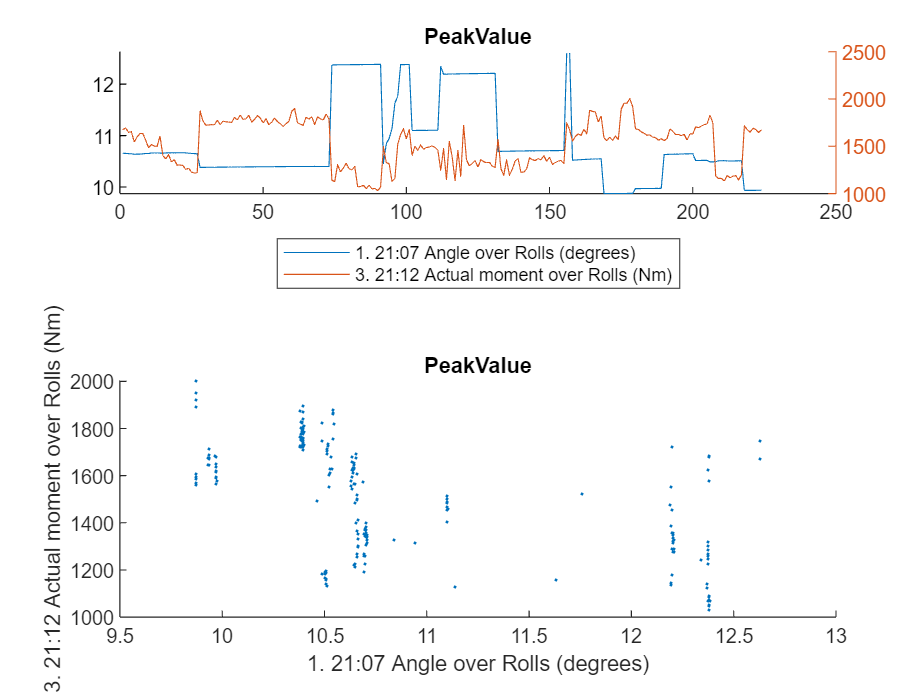

Signal 1:Signal 5 - Features: 1

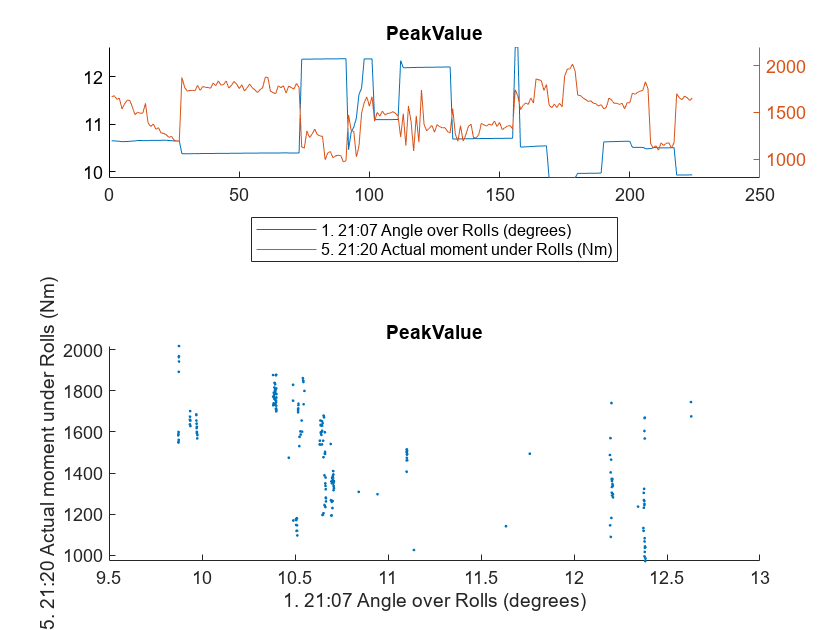

Signal 1:Signal 6 - Features: 4

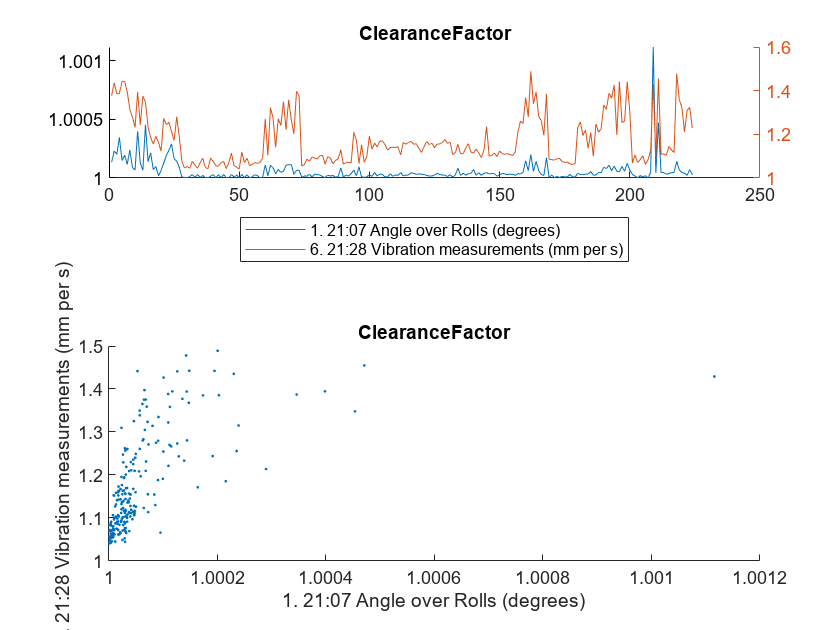

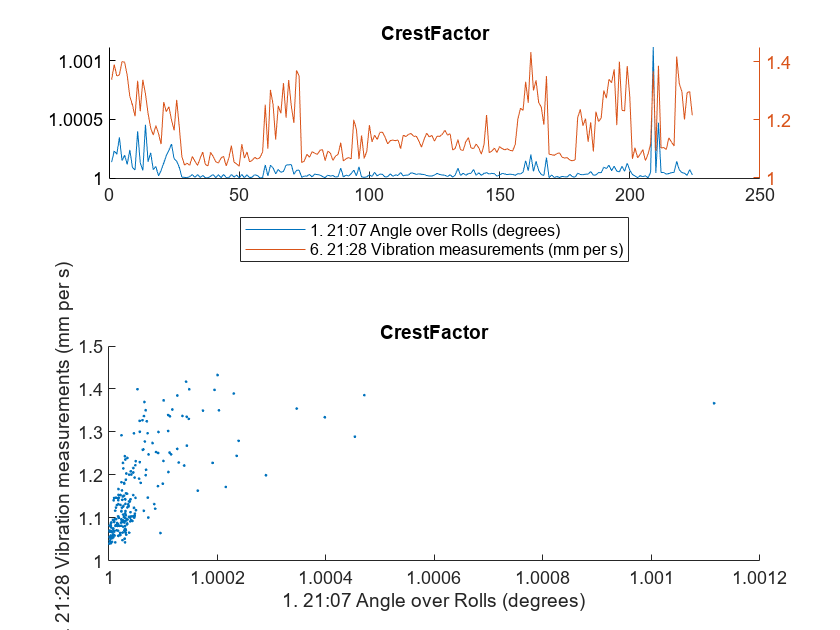

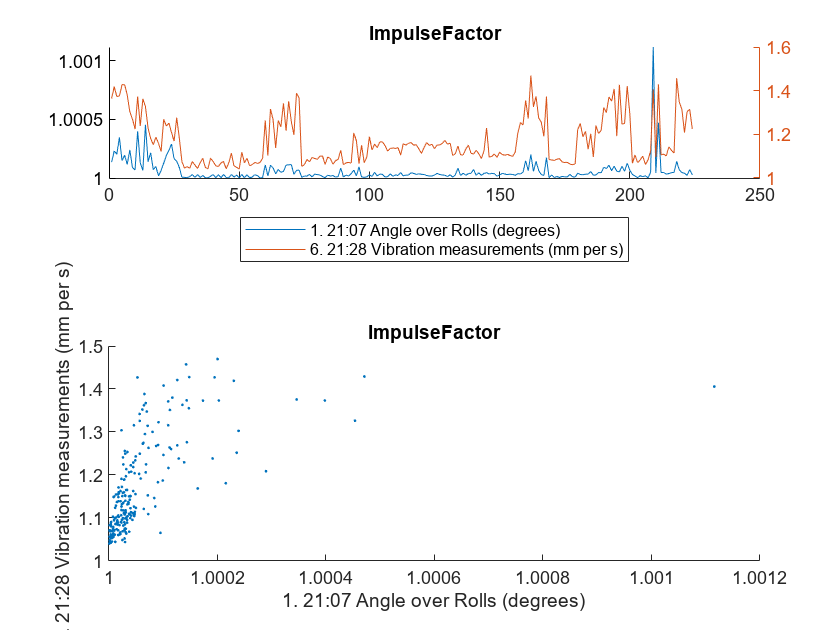

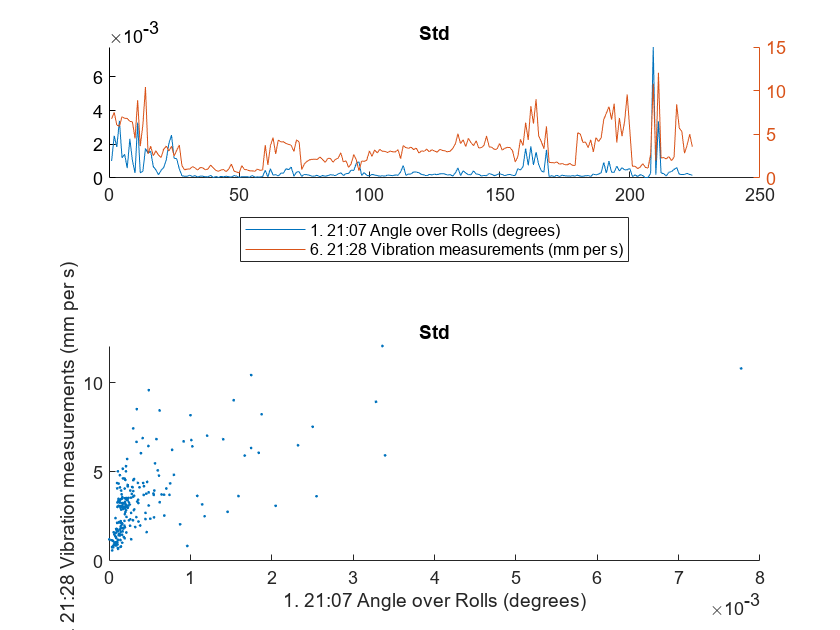

Signal 1:Signal 7 - Features: 3

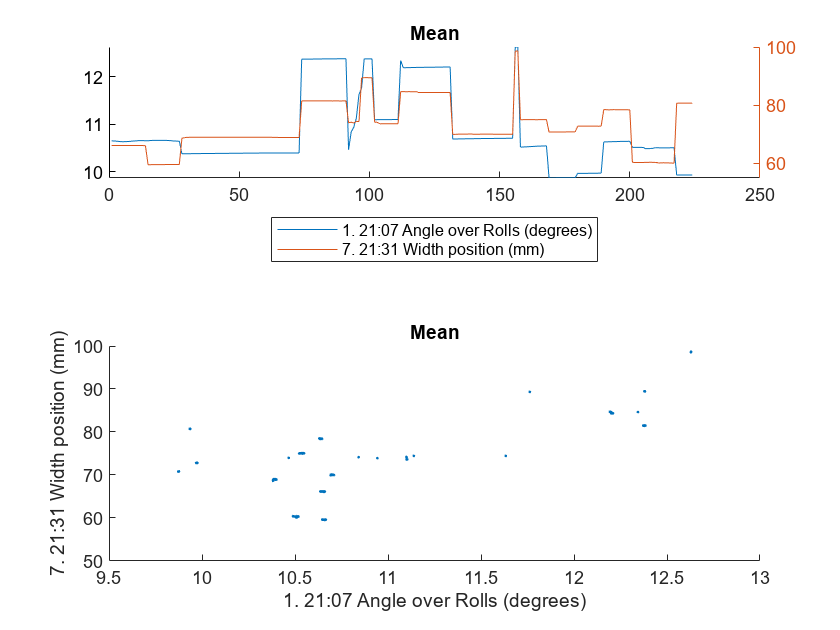

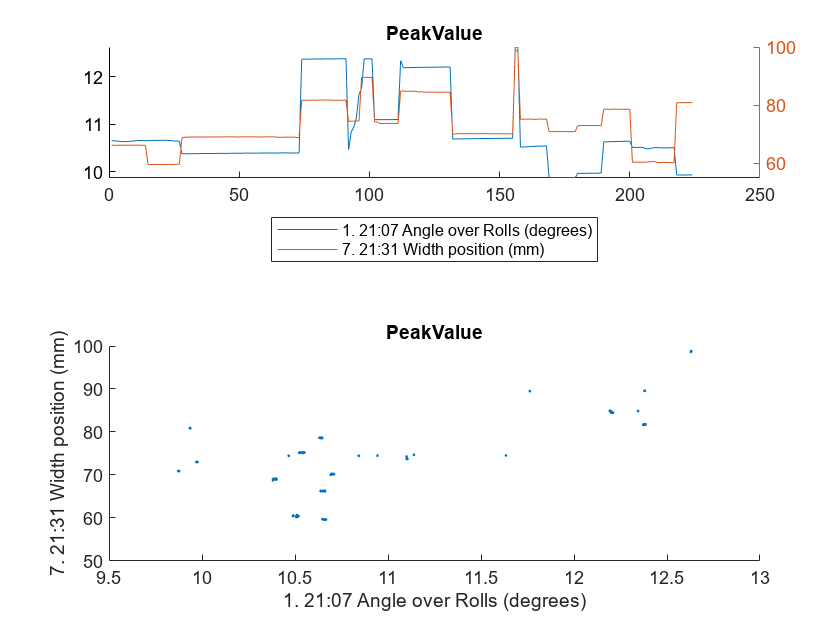

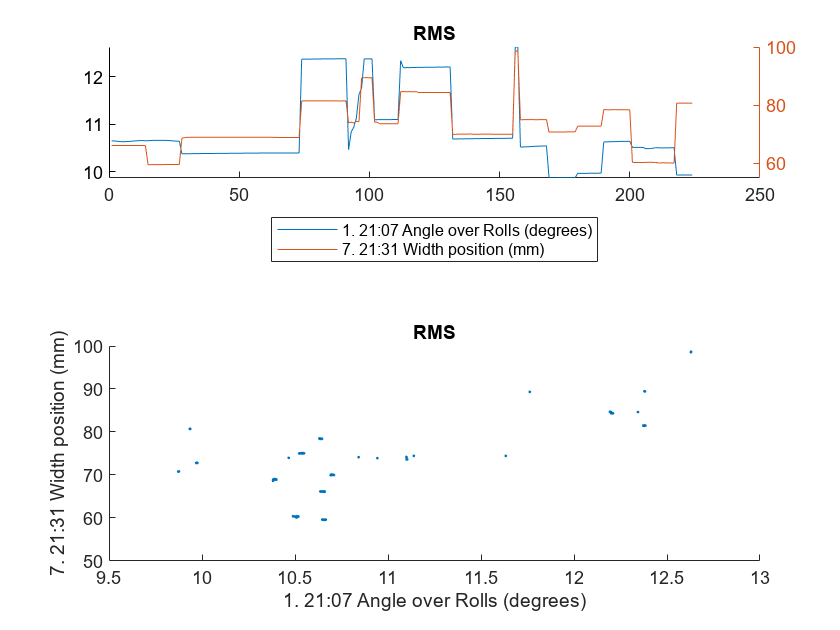

Signal 3:Signal 4 - Features: 2

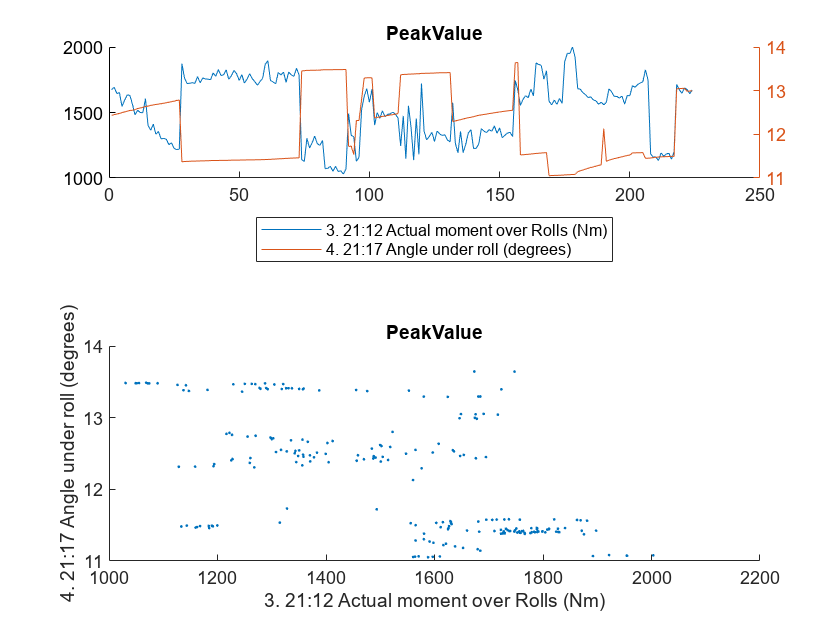

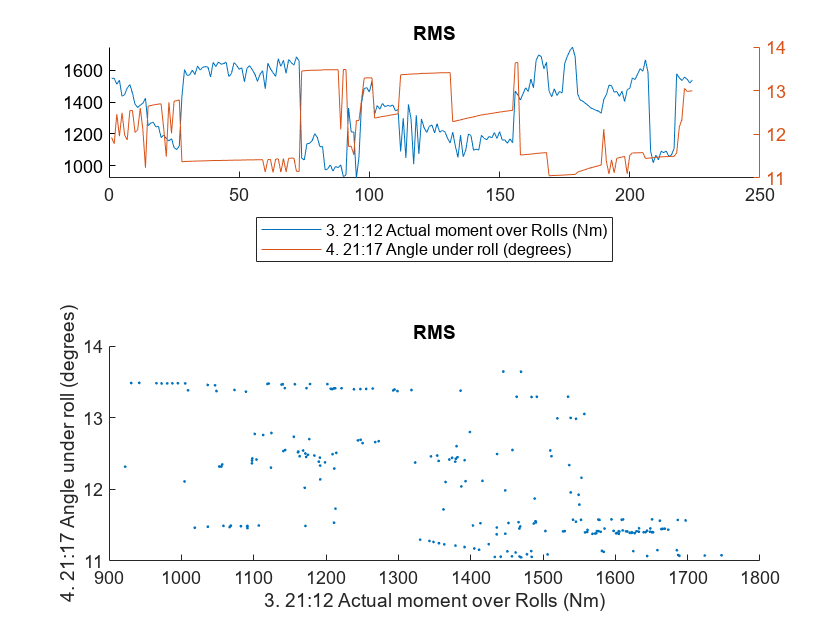

Signal 4:Signal 5 - Features: 2

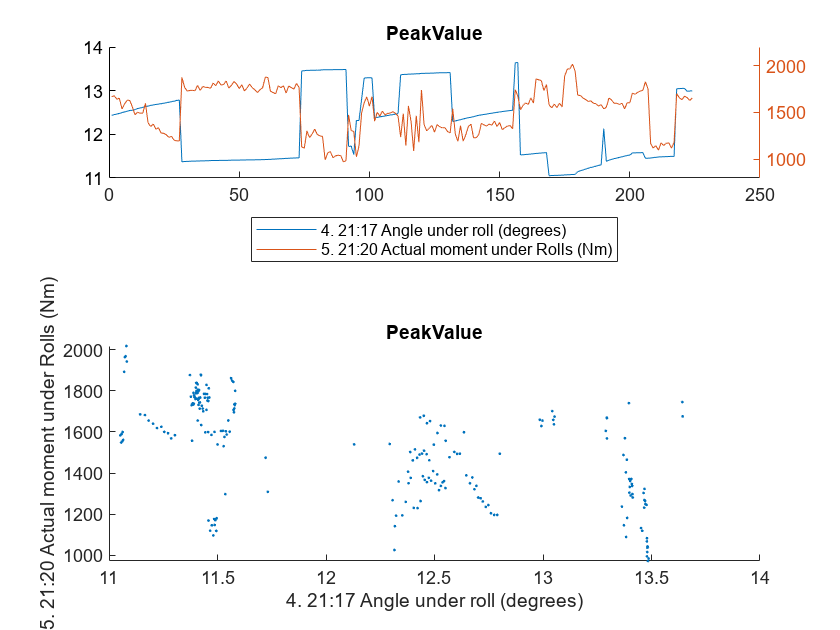

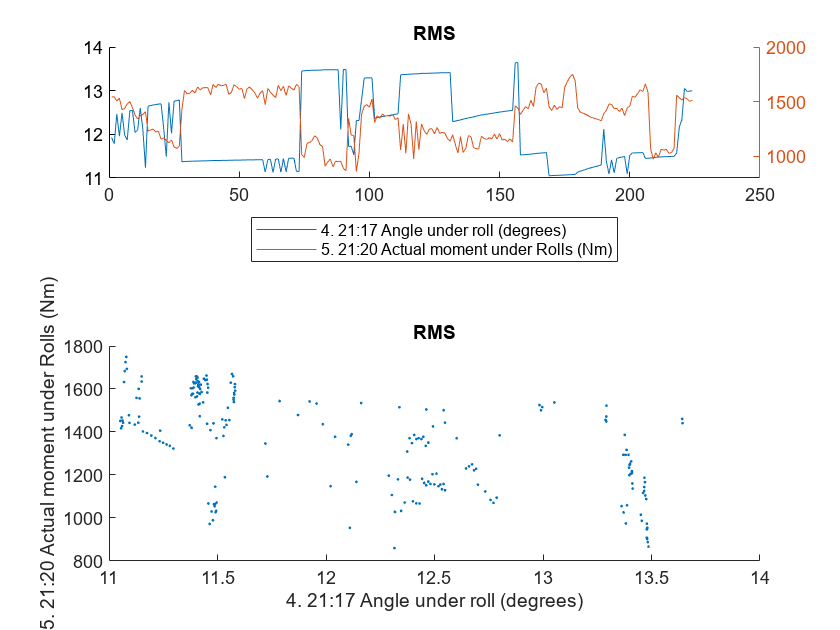

Signal 4:Signal 7 - Features: 1

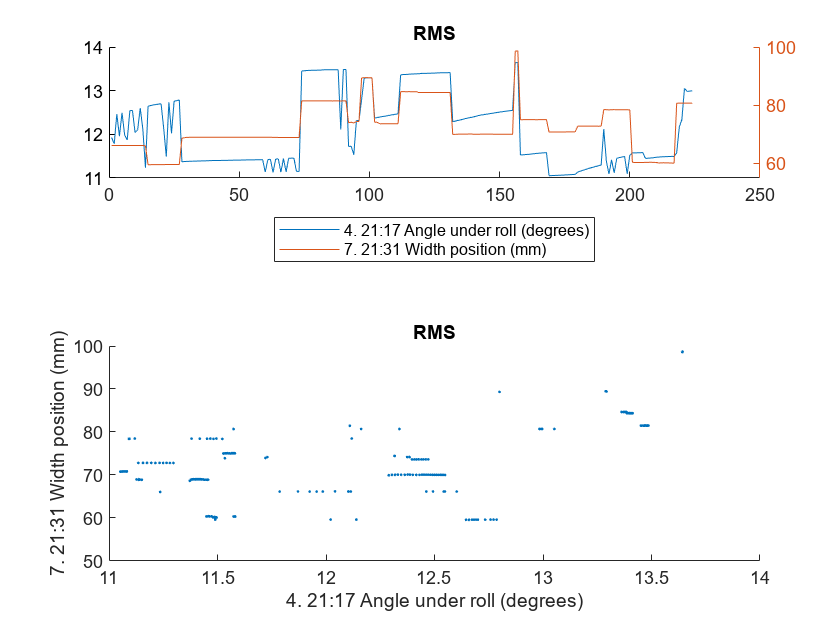

Signal 6:Signal 12 - Features: 1

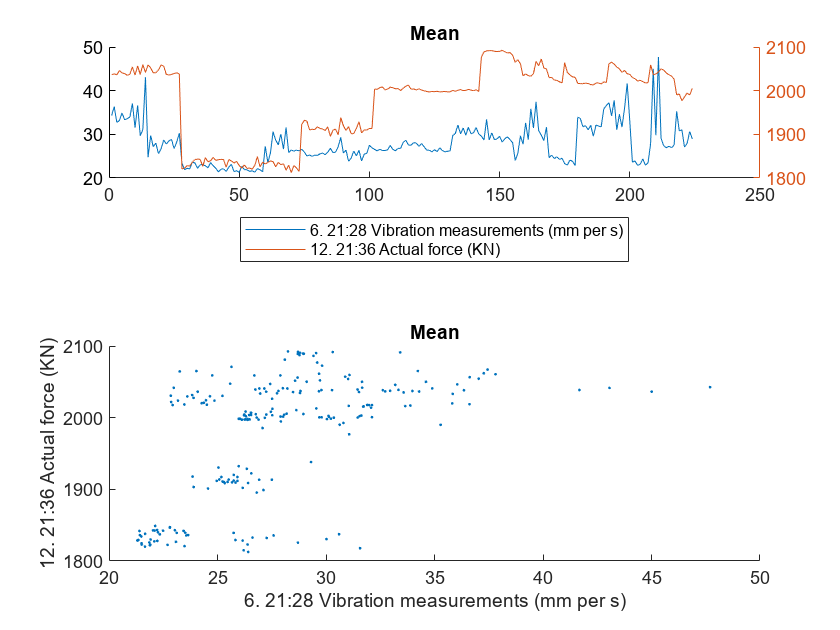

Signal 7:Signal 10 - Features: 1

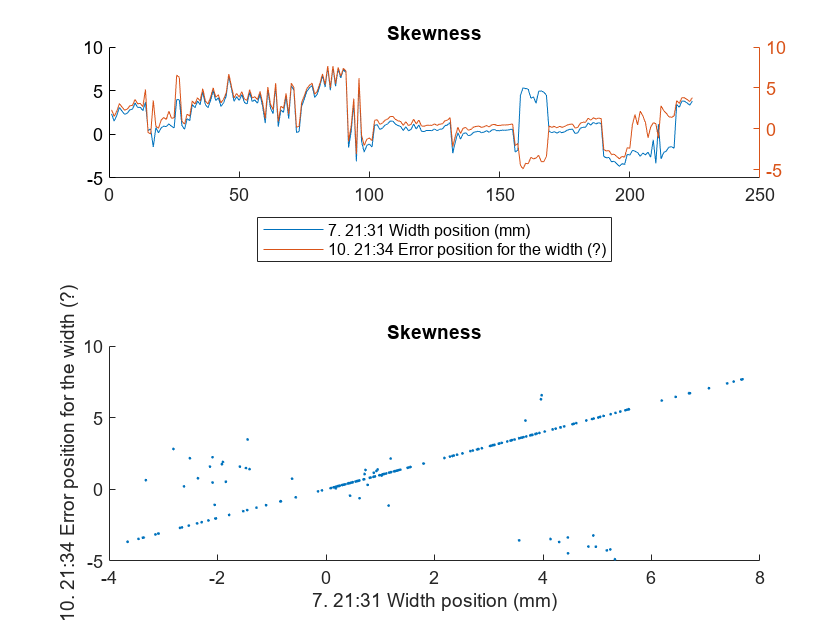

Signal 8:Signal 9 - Features: 1

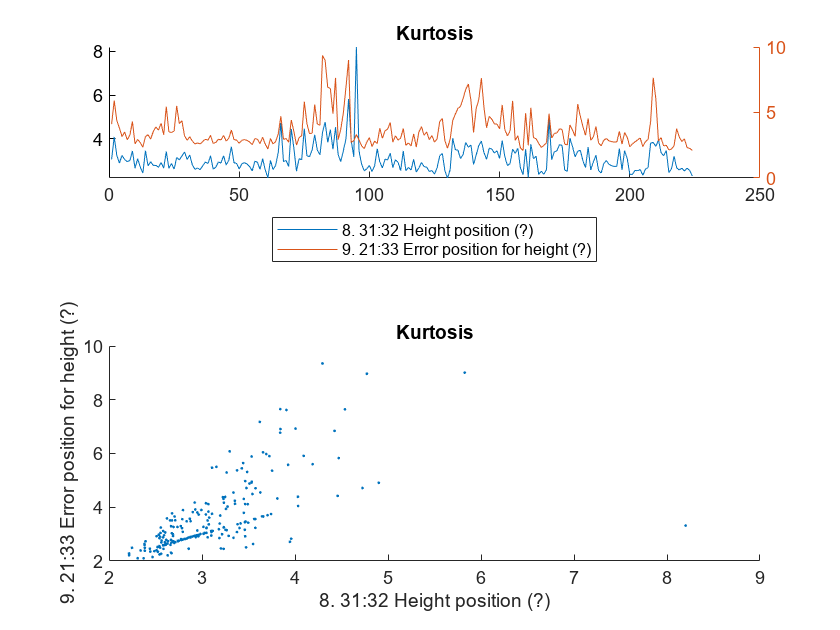

Signal 8:Signal 11 - Features: 1

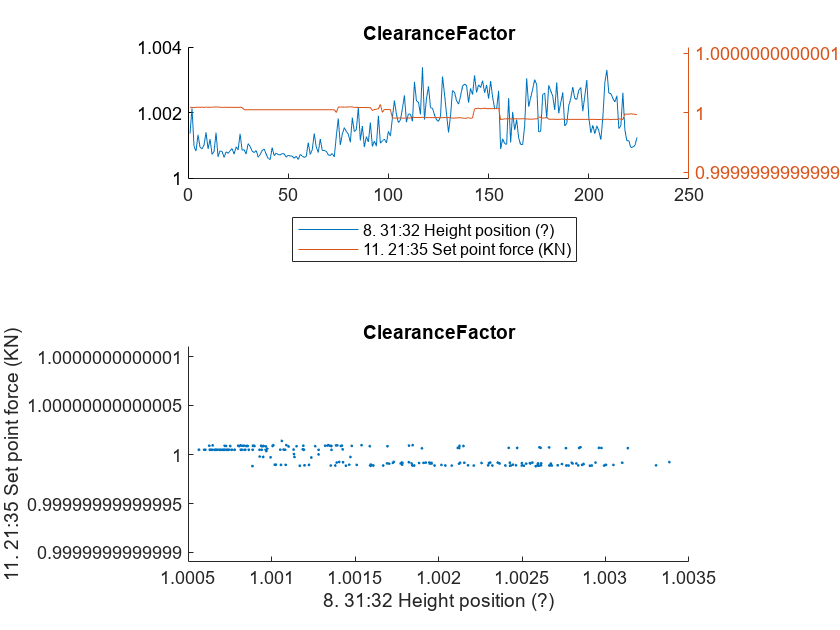

Signal 9:Signal 10 - Features: 3

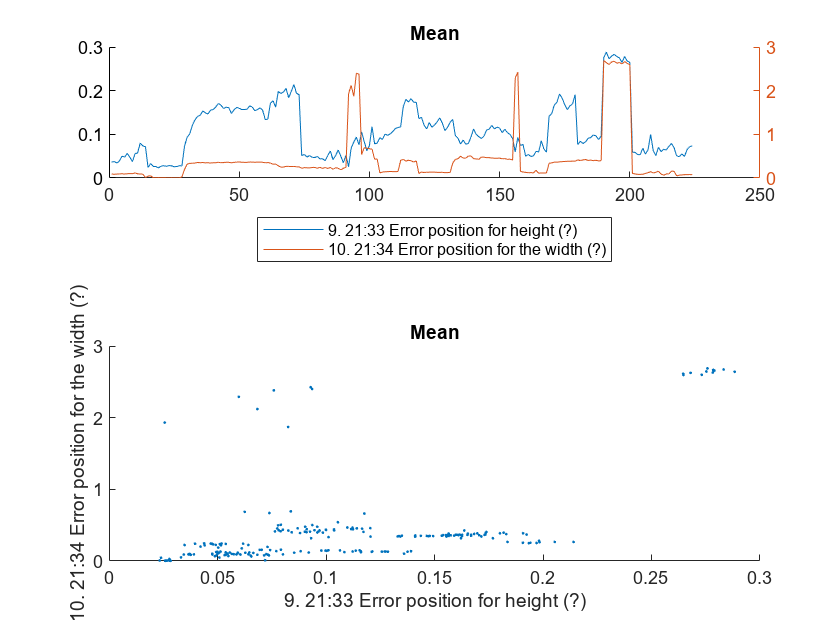

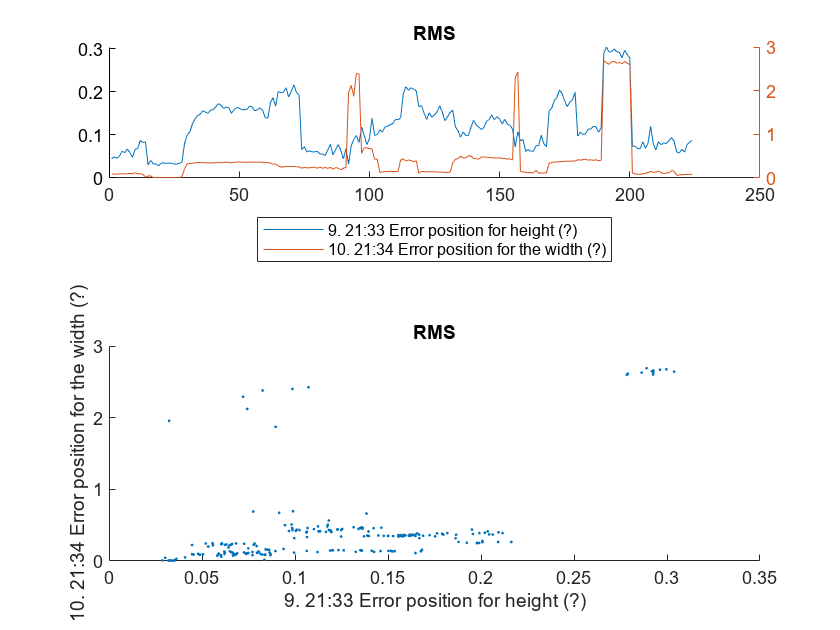

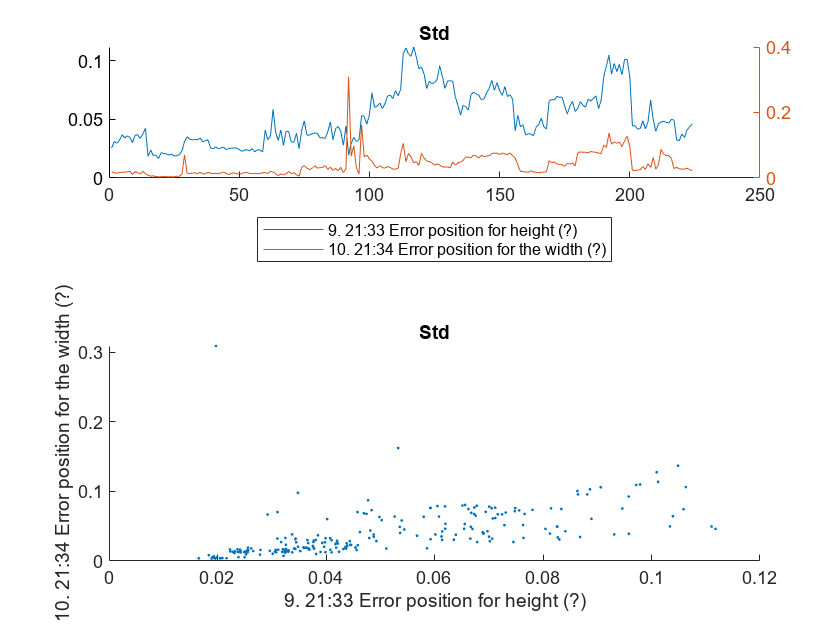

for i=1:numOfSignals
    for j=1:numOfSignals
        if (size(correlatedSignalMatrix{i,j}, 2))
            fprintf("Signal %i:Signal %i - Features: %i", i, j, size(correlatedSignalMatrix{i,j}, 2));
            plotCorrelatedSignals(i, j, correlatedSignalMatrix{i,j}, sensorNames, featureNames, signalName, FeaturesAll)
        end
    end
end

## Plot signals vs each other

% for i=1:numOfSignals
%     for j=1:numOfSignals
%         if (size(correlatedSignalMatrix{i,j}, 2))
%             fprintf("Signal %i:Signal %i - Features: %i", i, j, size(correlatedSignalMatrix{i,j}, 2));
%             plotCorrelatedSignals_XYaxis(i, j, correlatedSignalMatrix{i,j}, sensorNames, featureNames, signalName, FeaturesAll)
%         end
%     end
% end

## Plot correlated features for same signal

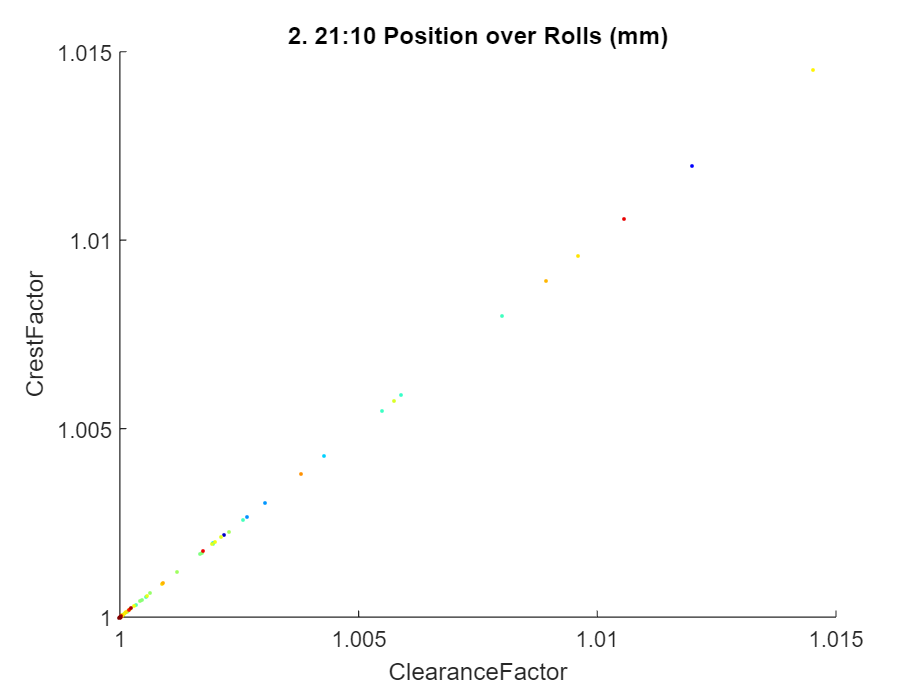

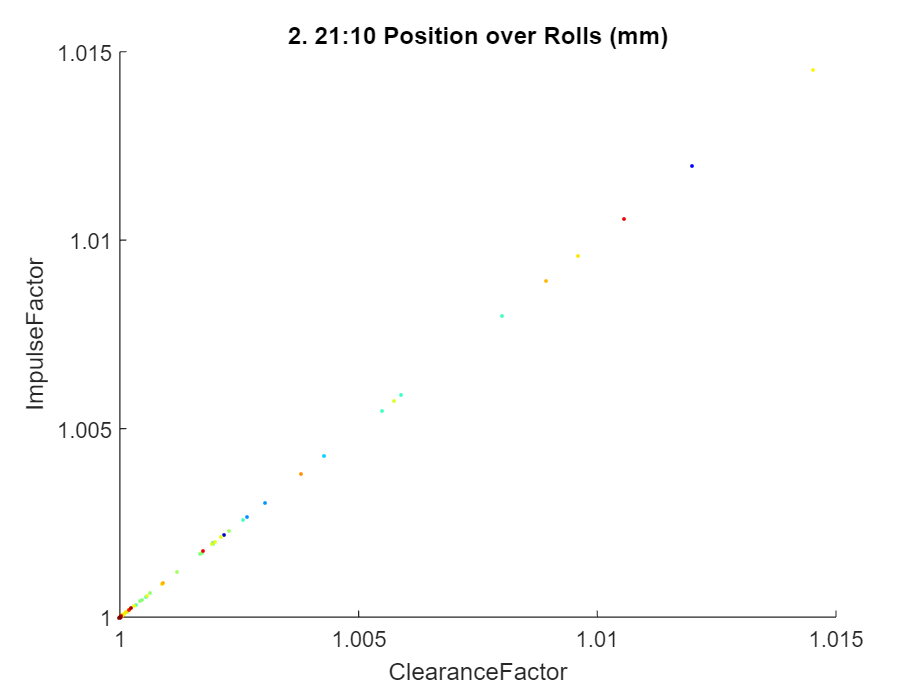

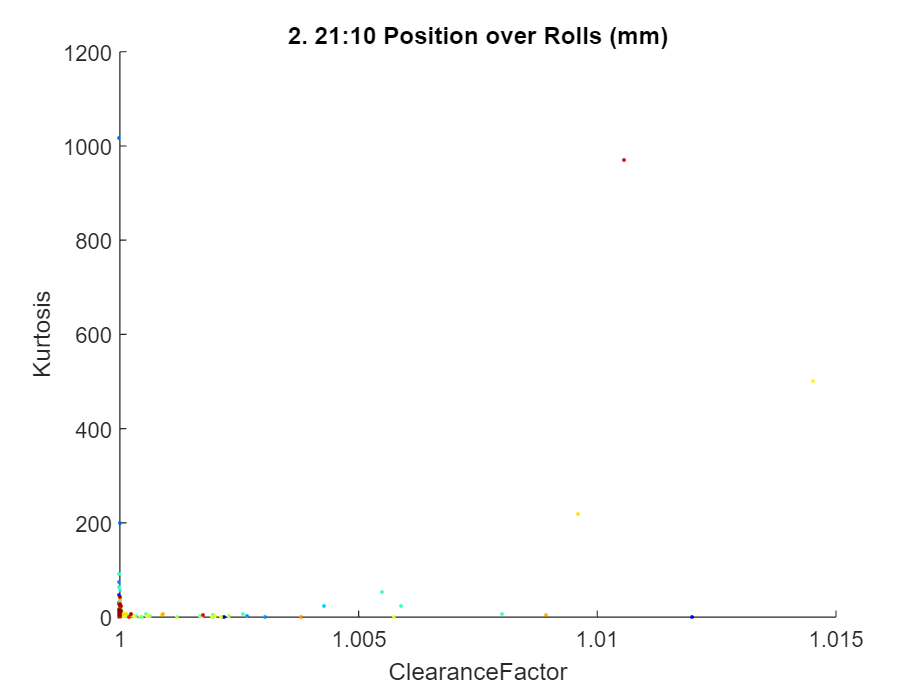

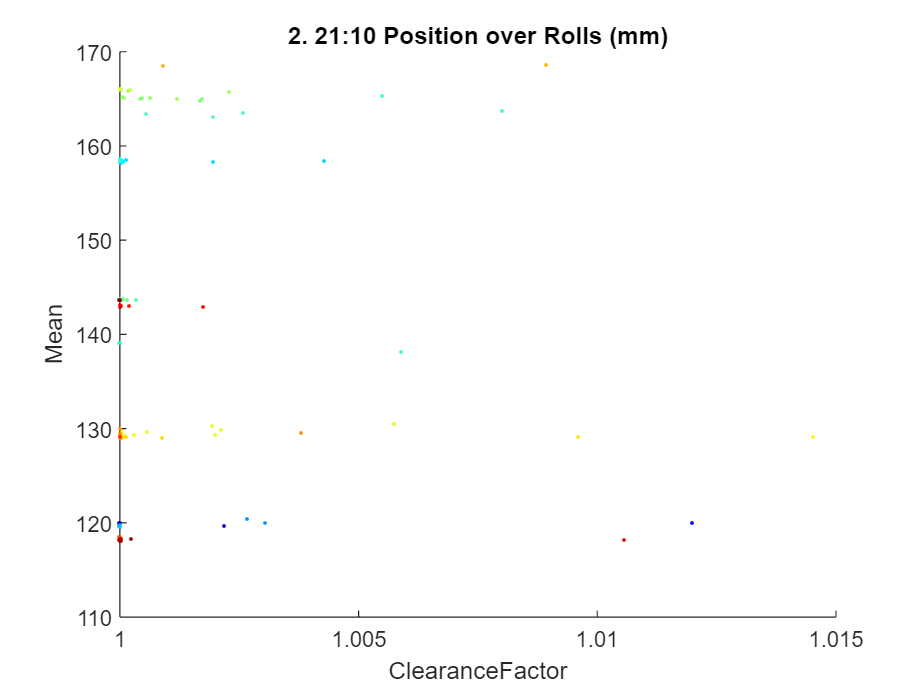

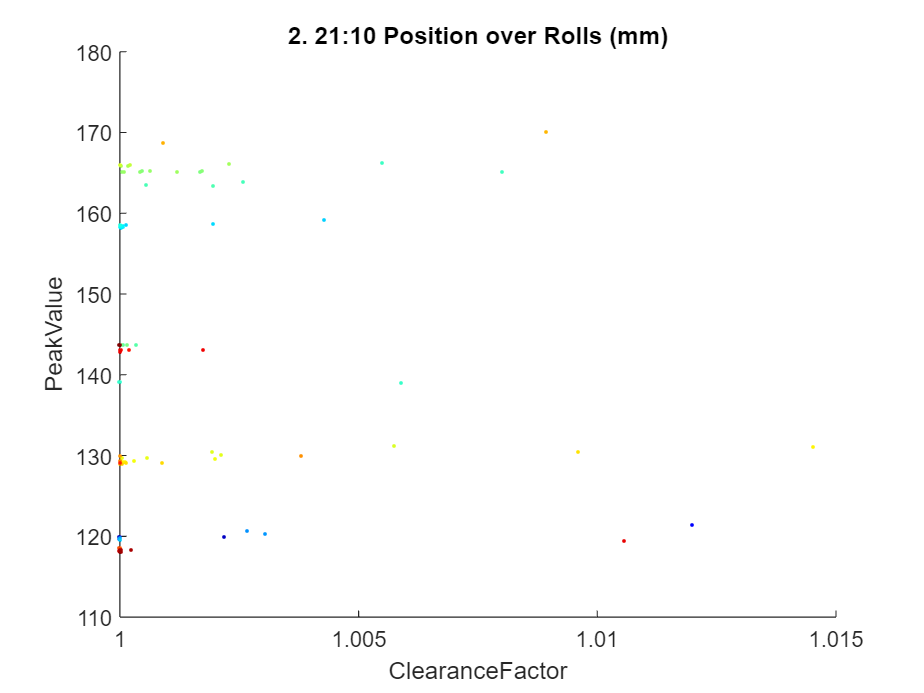

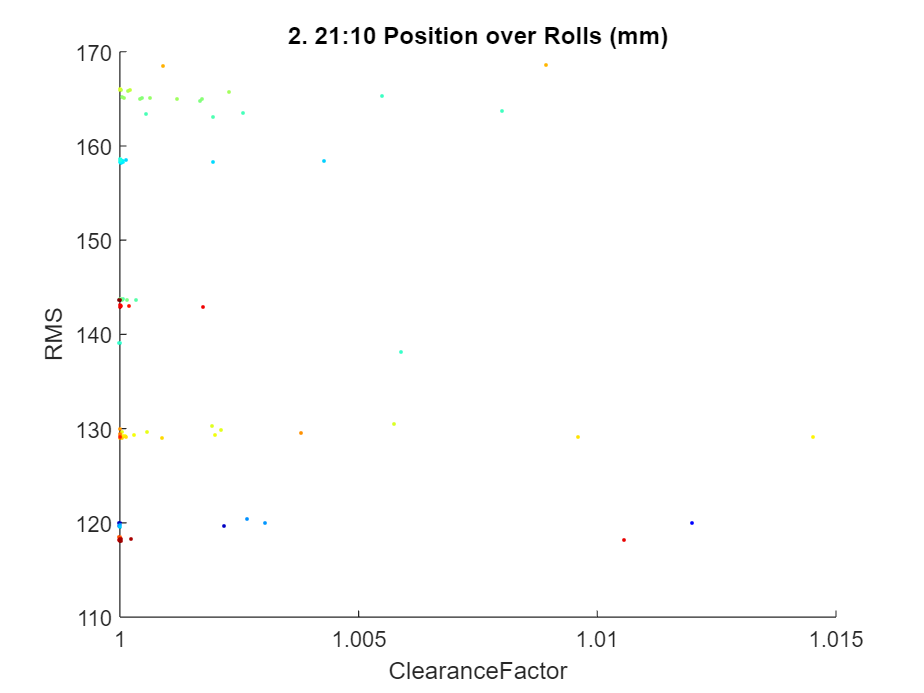

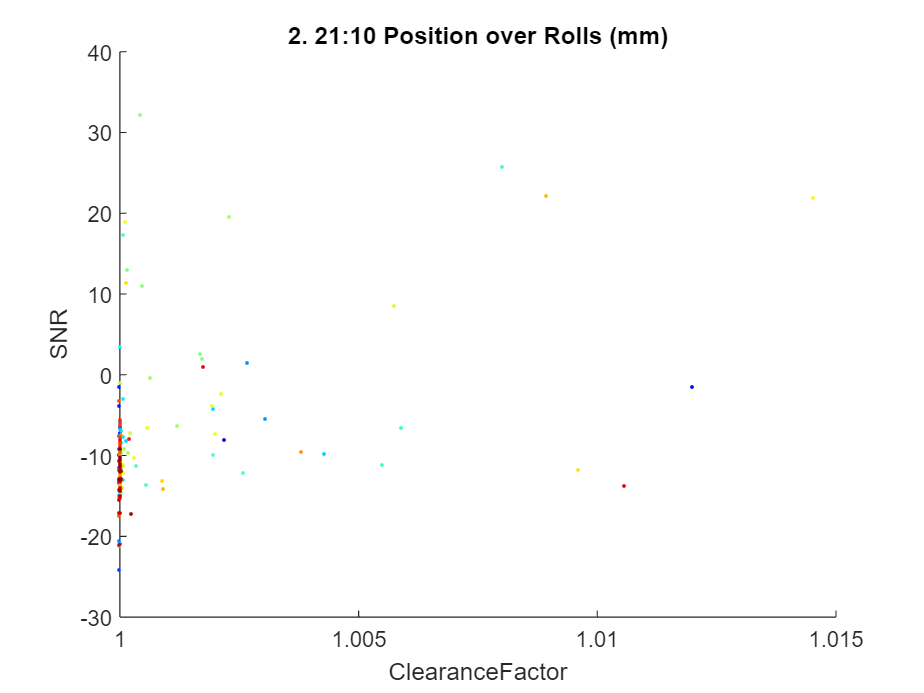

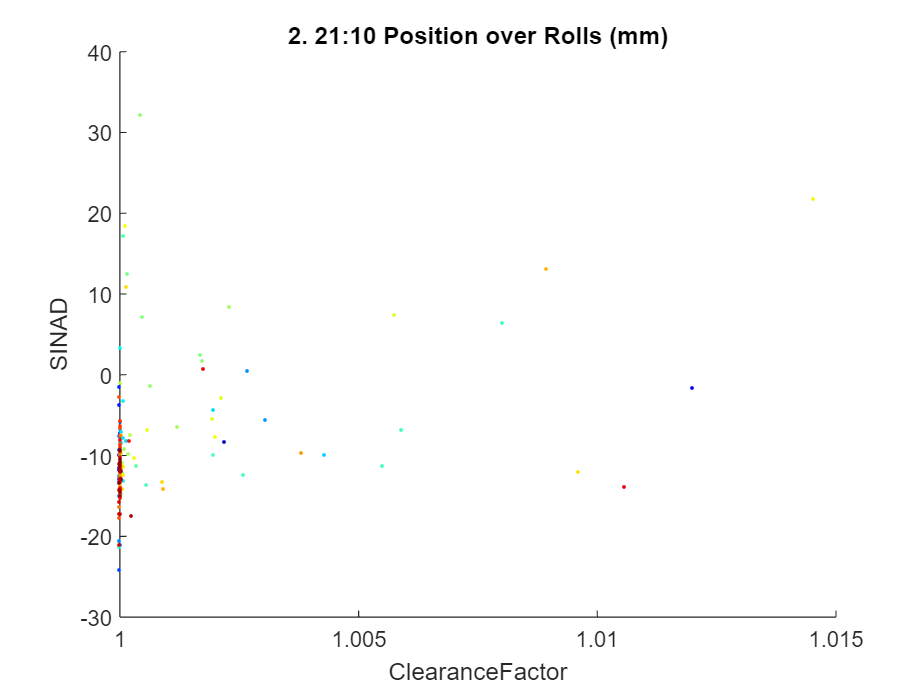

totalPlots = 78

%% Statistical Features: Shape Factor, Skewness, Kurtosis
%% Impulsive Metrics: Peak, Impulse, Crest, Clearance
%% Signal Processing Metrics: SNR, THD, SINAD

signalNum = 2;
%for signalNum = 1 : 12
    plotCorrelatedFeatures(signalNum, sensorNames, featureNames, signalName, FeaturesAll)

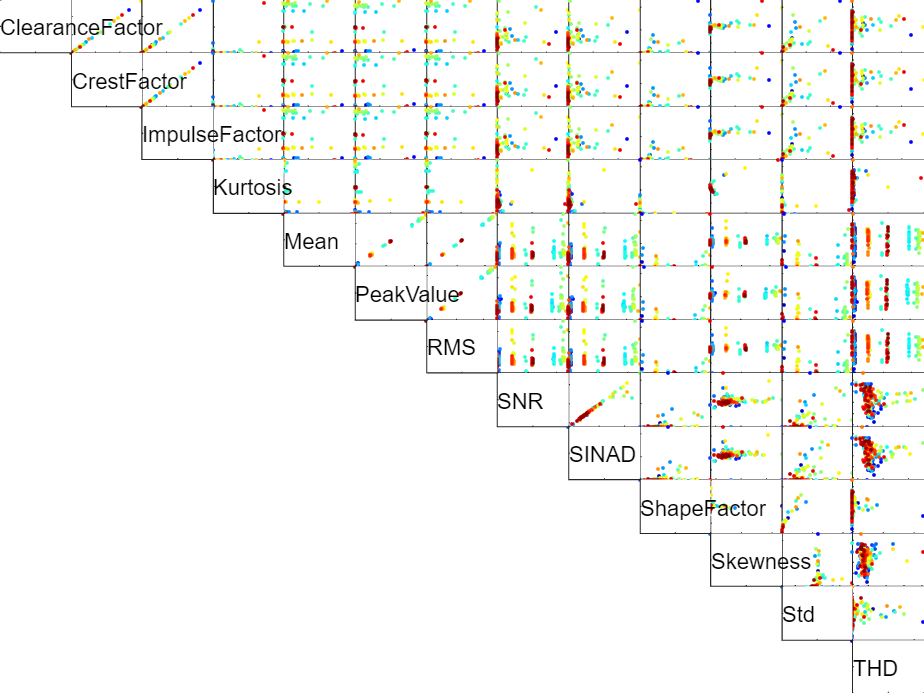

%end

## Function to plot two signals in time domain

function [] = plotCorrelatedSignals(signalNum1, signalNum2, correlatedFeatures, sensorNames, featureNames, signalName, FeaturesAll)
    for i=1:size(correlatedFeatures, 2)
        figure(); 
        subplot(2, 1, 1); hold on;
        feature = featureNames(correlatedFeatures(i));
        plot(FeaturesAll.(signalName(signalNum1) + feature));
        yyaxis right;
        plot(FeaturesAll.(signalName(signalNum2) + feature));
        legend(sensorNames(signalNum1), sensorNames(signalNum2), "Location", 'southoutside');
        title(feature);

        subplot(2, 1, 2); 
        feature = featureNames(correlatedFeatures(i));
        scatter(FeaturesAll.(signalName(signalNum1) + feature), FeaturesAll.(signalName(signalNum2) + feature), 2, 'filled');
        xlabel(sensorNames(signalNum1))
        ylabel(sensorNames(signalNum2));
        title(feature);
    end
end

## Function to plot one signal feature against the same feature of another signal

% function [] = plotCorrelatedSignals_XYaxis(signalNum1, signalNum2, correlatedFeatures, sensorNames, featureNames, signalName, FeaturesAll)
%      for i=1:size(correlatedFeatures, 2)
%         figure();
%         feature = featureNames(correlatedFeatures(i));
%         scatter(FeaturesAll.(signalName(signalNum1) + feature), FeaturesAll.(signalName(signalNum2) + feature), 'filled');
%         xlabel(sensorNames(signalNum1))
%         ylabel(sensorNames(signalNum2));
%         title(feature);
%     end
% end

## Function to plot one feature against a different feature

function [] = plotCorrelatedFeatures(signalNum, sensorNames, featureNames, signalName, FeaturesAll)
    totalPlots = 0;
    numpoints = size(FeaturesAll.(signalName(signalNum) + featureNames(1)), 1);
    pointidx = 1 : numpoints; 
    for i = 1:size(featureNames, 2)
        feature1 = featureNames(i);
        for j = i+1 : size(featureNames, 2)
            figure();
            feature2 = featureNames(j);
            scatter(FeaturesAll.(signalName(signalNum) + feature1), FeaturesAll.(signalName(signalNum) + feature2), 3, pointidx, 'filled');
            colormap( jet (numpoints) )
            xlabel(feature1);
            ylabel(feature2);
            title(sensorNames(signalNum));
            totalPlots = totalPlots + 1;
        end
    end
    totalPlots
end